# Robust Control of an Active Suspension - Modified Matlab Example

## Quarter-Car Suspension Model

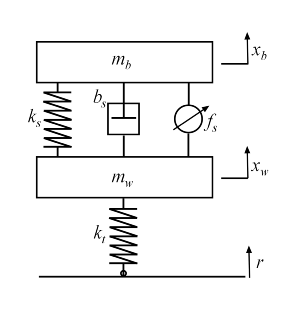

clear;
% physical parameters
mb = 300;       % kg
mw = 60;        % kg
bs = 1000;      % N/m/s
ks = 16000;     % N/m
kt = 190000;    % N/m

% State matrices
A = [   0 1 0 0; [-ks -bs ks bs]/mb; ...
        0 0 0 1; [ks bs -ks-kt -bs]/mw];
B = [0 0; 0 1e3/mb; 0 0; [kt -1e3]/mw];
C = [1 0 0 0; 1 0 -1 0; A(2,:)];
D = [0 0; 0 0; B(2,:)];

qcar = ss(A,B,C,D);
qcar.StateName = {'body travel (m)'; 'body vel (m/s)';...
                'Wheel travel (m)'; 'wheel vel (m/s)'};

qcar.InputName = {'r';'fs'};
qcar.OutputName = {'xb'; 'sd'; 'ab'};

% Nominal Actuator Model
ActNom = tf(1, [1/60 1]);
ActNom.InputName = 'u';
ActNom.OutputName = 'fs';

## Design Setup

% Weights
Wroad = ss(0.07);  Wroad.u = 'd'; Wroad.y = 'r';
Wact = 0.8*tf([1 50], [1 500]); Wact.u = 'u'; Wact.y = 'e1';

HandlingTarget = 0.04 * tf([1/8 1], [1/80 1]);
ComfortTarget = 0.4 * tf([1/0.45 1], [1/150 1]);

% Three design points
beta = reshape([0.01 0.5 0.99],[1 1 3]);
Wsd = beta / HandlingTarget;
Wsd.u = 'sd'; Wsd.y = 'e3';
Wab = (1-beta)/ComfortTarget;
Wab.u = 'ab'; Wab.y = 'e2';


## Connect the parts together into a single open loop model (car, actuator, weights)

sdmeas = sumblk('y1 = sd');
abmeas = sumblk('y2 = ab');
ICinputs = {'d'; 'u'};
ICoutputs = {'e1';'e2';'e3';'y1';'y2'};
qcaric = connect(qcar(2:3,:), ActNom, Wroad, Wact, Wab, Wsd, ...
    sdmeas, abmeas, ICinputs, ICoutputs);

## Nominal H-Infinity Design

Use hinfsyn to compute an H$\infty$ controller for each value of the  blending factor $\beta$

ncont = 1; % one control signal, u
nmeas = 2; % two measurement signals, sd and ab
K = ss(zeros(ncont,nmeas,3));
gamma = zeros(3,1);
for i=1:3
    [K(:,:,i),~,gamma(i)] = hinfsyn(qcaric(:,:,i), nmeas, ncont);
end


## Build the closed loop system

K.u = {'sd','ab'}; K.y = 'u';
CL = connect(qcar, ActNom, K, 'r', {'xb';'sd';'ab'});

## Time-Domain Evaluation

To further evaluate the three design s, perform time-domain  simulations using a road disturbance signal *r(t)* representing a road bump of height 5 cm

% Road distubance
t = 0:0.0025:1;
roaddist = zeros(size(t));
roaddist(1:101) = 0.025 * (1-cos(8*pi*t(1:101)));

%Simulate
p1 = lsim(qcar(:,1),roaddist,t);    % Open loop
y1 = lsim(CL(1:3,1,1), roaddist,t)  % comfort

y1 =          0         0         0
    0.0000   -0.0000    0.0006
    0.0000   -0.0000    0.0039
    0.0000   -0.0000    0.0121
    0.0000   -0.0000    0.0277
    0.0000   -0.0000    0.0529
    0.0000   -0.0001    0.0894
    0.0000   -0.0002    0.1388
    0.0000   -0.0003    0.2023
    0.0000   -0.0005    0.2809


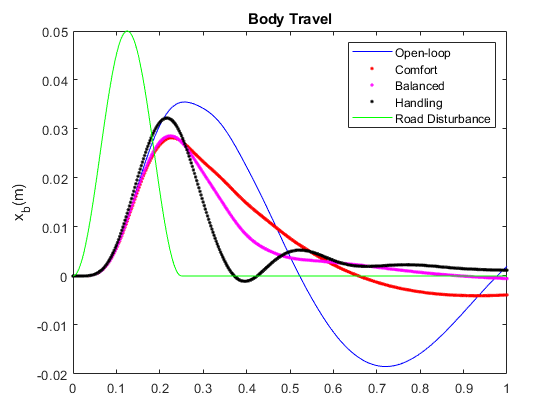

y2 = lsim(CL(1:3,1,2),roaddist,t);  % Balanced
y3 = lsim(CL(1:3,1,3),roaddist,t);  % Handling

% Plot results
plot(t,p1(:,1),'b',t,y1(:,1),'r.',t, y2(:,1),'m.',t, y3(:,1), 'k.', t, roaddist, 'g')
title('Body Travel'), ylabel('x_b(m)')
legend('Open-loop', 'Comfort', 'Balanced', 'Handling', 'Road Disturbance', 'location', 'northeast')